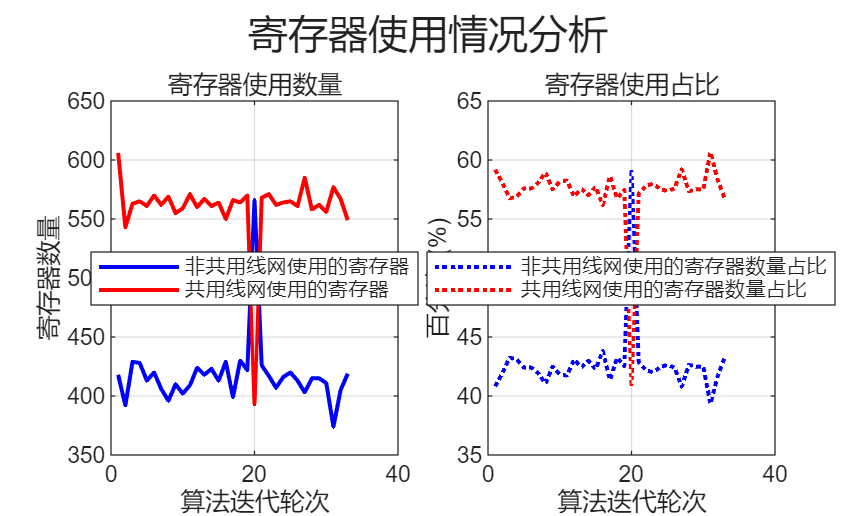

cycle = [1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11, 12, 13, 14, 15, 16, 17, 18, 19, 20, 21, 22, 23, 24, 25, 26, 27, 28, 29, 30, 31, 32, 33];
has_non_reuse = [418, 392, 429, 428, 413, 420, 406, 396, 410, 402, 409, 424, 418, 423, 413, 429, 399, 430, 422, 566, 426, 417, 407, 416, 420, 413, 403, 415, 415, 411, 374, 405, 419];
only_reuse = [606, 543, 563, 565, 561, 570, 562, 569, 555, 559, 571, 560, 567, 561, 564, 550, 566, 564, 570, 393, 568, 571, 562, 564, 565, 561, 585, 558, 562, 556, 577, 567, 549];

total_use = has_non_reuse + only_reuse;
has_non_reuse_ratio = has_non_reuse ./ total_use * 100;
only_reuse_ratio = only_reuse ./ total_use * 100;

% 创建子图
figure;

% 左子图 - 显示寄存器数量
subplot(1,2,1);
plot(cycle, has_non_reuse, 'b-', 'LineWidth', 1.5);
hold on;
plot(cycle, only_reuse, 'r-', 'LineWidth', 1.5);
% scatter(1, basiccost_has_non_reuse, 50, 'g', 'fill');
% scatter(1, basiccost_only_reuse, 50, 'g', 'fill');
ylabel('寄存器数量');
xlabel('算法迭代轮次');
legend({'非共用线网使用的寄存器','共用线网使用的寄存器'}, 'Location','best');
title('寄存器使用数量');
grid on;

% 右子图 - 显示百分比
subplot(1,2,2);
plot(cycle, has_non_reuse_ratio, 'b:', 'LineWidth', 1.5);
hold on;
plot(cycle, only_reuse_ratio, 'r:', 'LineWidth', 1.5);
ylabel('百分比 (%)');
xlabel('算法迭代轮次');
legend({'非共用线网使用的寄存器数量占比','共用线网使用的寄存器数量占比'}, 'Location','best');
title('寄存器使用占比');
grid on;

% 调整整体标题（可选）
sgtitle('寄存器使用情况分析');